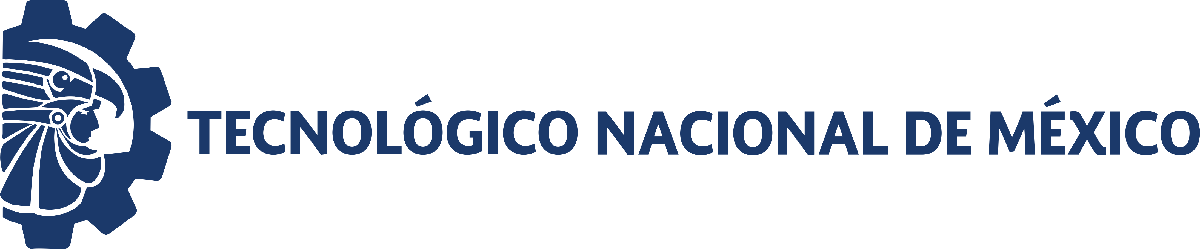                                 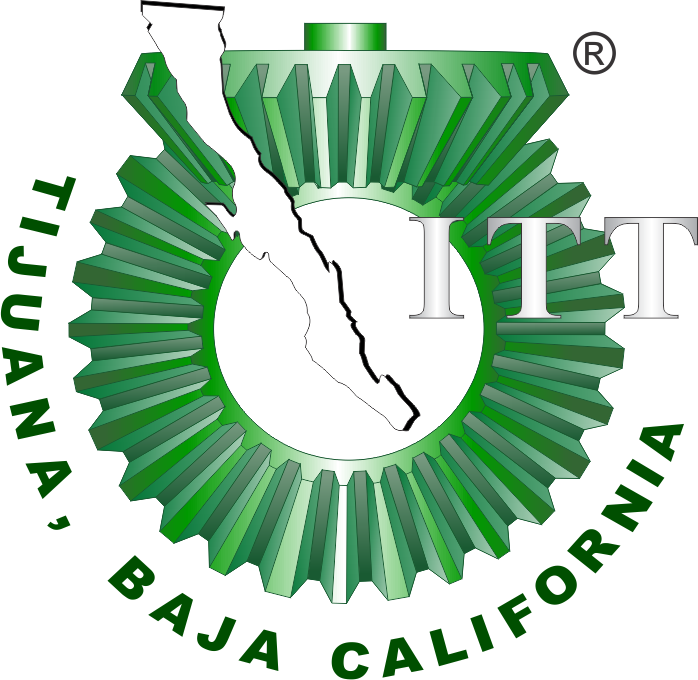

# Práctica cuatro: Diseño del sistema endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

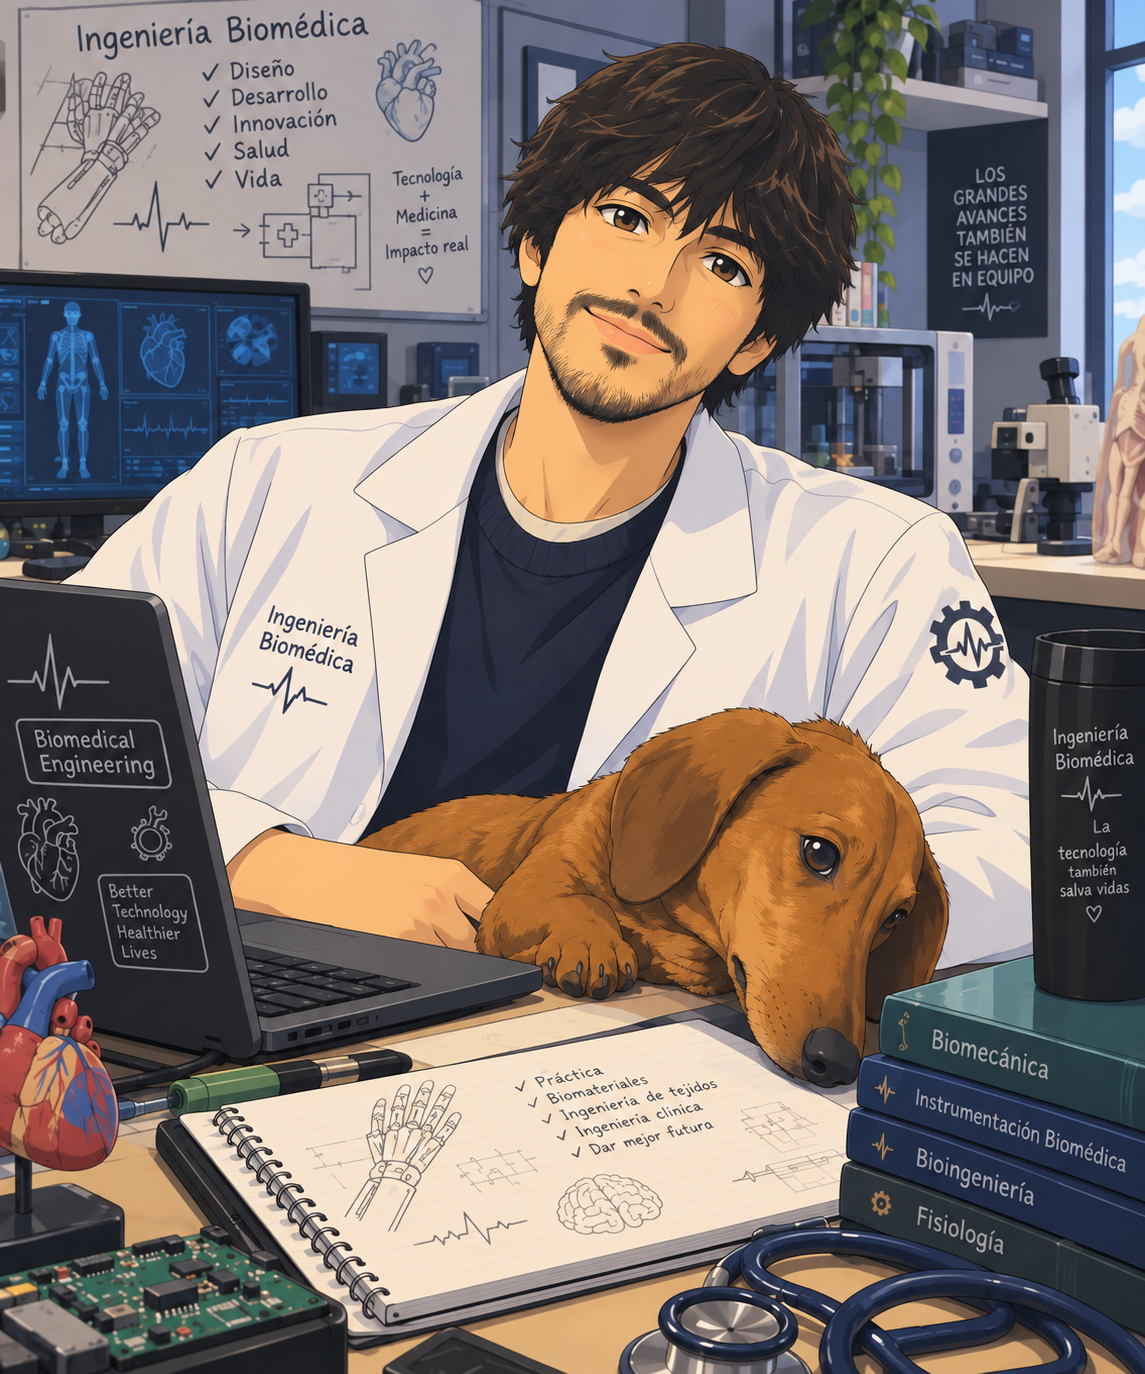

Nombre del alumno: Martin Alonso Gonzalez Holguin

Número de control: 23212198

Correo institucional: l23212198**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('P4')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('P4',parameters);
x.who

This Simulink.SimulationOutput object contains these editable properties:

    Ve    caso    caso_CE    caso_EID    caso_FT    control    tout    



## Respuesta a la función sinusoidal

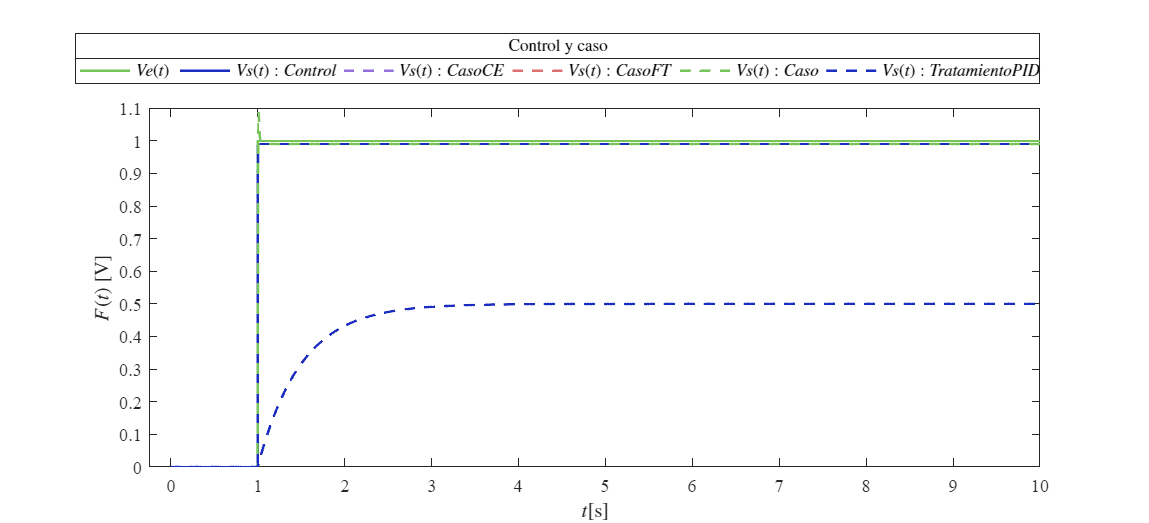

plotsignals(x.tout,x.control,x.caso_CE,x.caso_FT,x.caso,x.caso_EID,x.Ve)

Funcion: Respuesta de la simulacion 

function plotsignals(t,c,c1,c2,c3,c4,c5)

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,11,5])
set(gca,'fontname','times new roman','fontsize',11)

hold on; grid off; box on;

clr1 = [118, 196, 87]/255;
clr2 = [27, 44, 193]/255;
clr3 = [147, 112, 219]/255;
clr4 = [221, 113, 113]/255;

order = [clr1;clr2;clr3;clr4];
colororder(order)

plot(t,c5,'-',t,c,'-',t,c1,'--',t,c2,'--', ...
    t,c3,'--',t,c4,'--','LineWidth',1.5, ...
    'MarkerSize',5,'MarkerIndices',1:1e3:length(t));

L = legend('$Ve(t)$', ...
           '$Vs(t): Control$', ...
           '$Vs(t): Caso CE$', ...
           '$Vs(t): Caso FT$', ...
           '$Vs(t): Caso$', ...
           '$Vs(t): Tratamiento PID$');

set(L,'interpreter','latex','location','northoutside', ...
    'orientation','horizontal')

title(L,'Control y caso')
xlabel('$t$[s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')

xlim([-0.25 10]); xticks(0:1:10)
ylim([0 1.1]); yticks(0:0.1:1.1)

exportgraphics(gcf,'Control_caso_matlab4.pdf', ...
    'contenttype','vector')

end